7

G0=tf(conv([5 1],[1 1]), [1 -0 0 0]);G0=zpk(G0)

G0 =
 
  5 (s+1) (s+0.2)
  ---------------
        s^3
 
Continuous-time zero/pole/gain model.



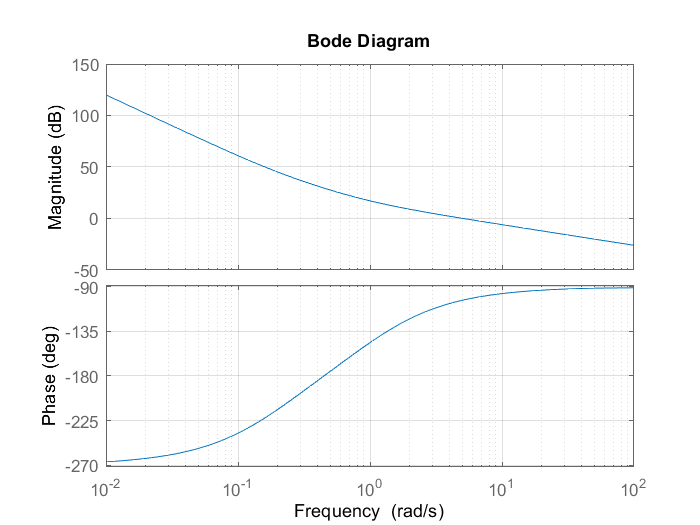

figure
bode(G0);
grid on;

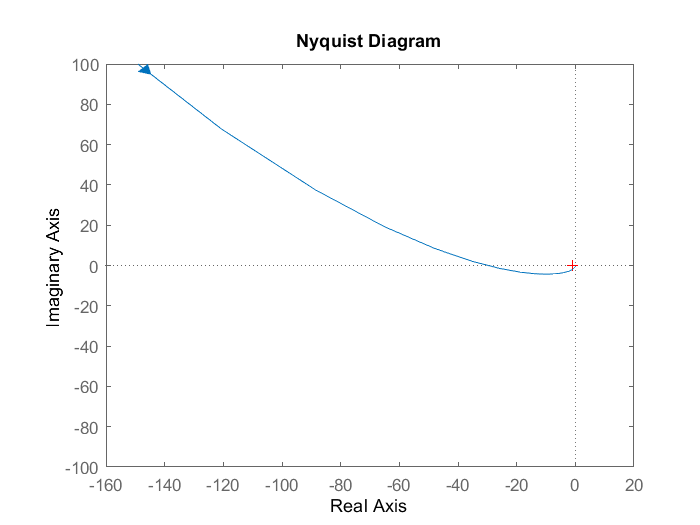


figure
P=nyquistplot(G0);
ylim([-100 100])
setoptions(P,'ShowFullContour','off')

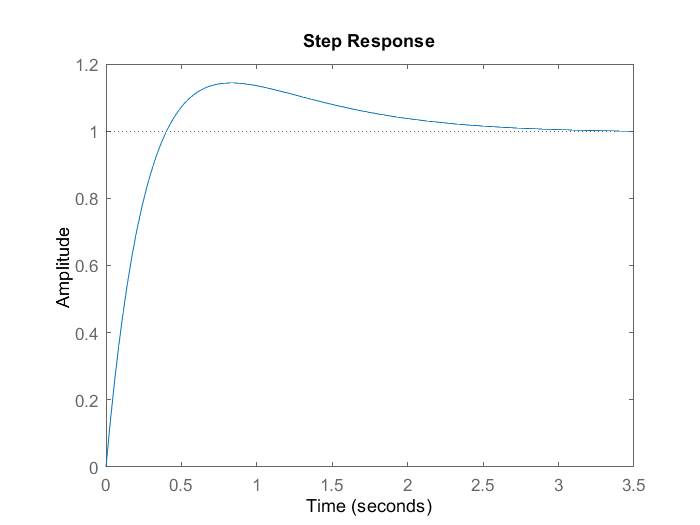


step(feedback(G0,1))

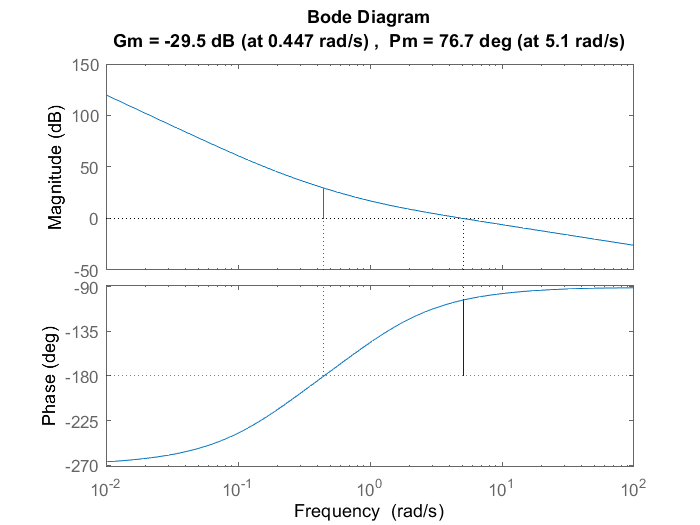

margin(G0)

13

G0=1*tf([1],conv([1 -0.1],[1 0]));G0=zpk(G0)

G0 =
 
      1
  ---------
  s (s-0.1)
 
Continuous-time zero/pole/gain model.



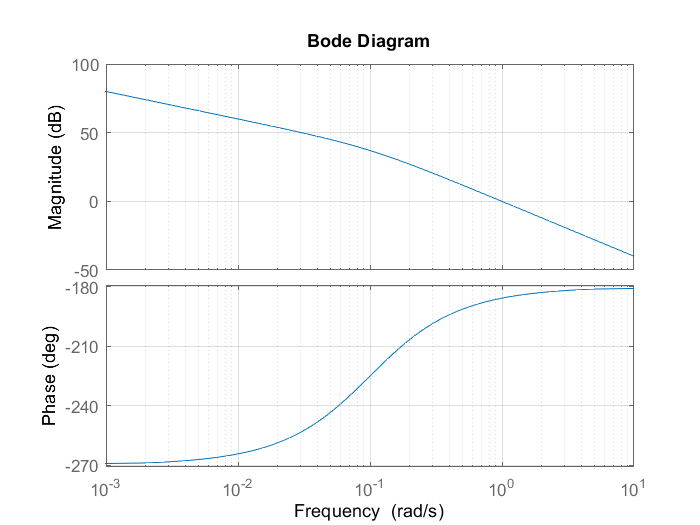

figure
bode(G0);
grid on;

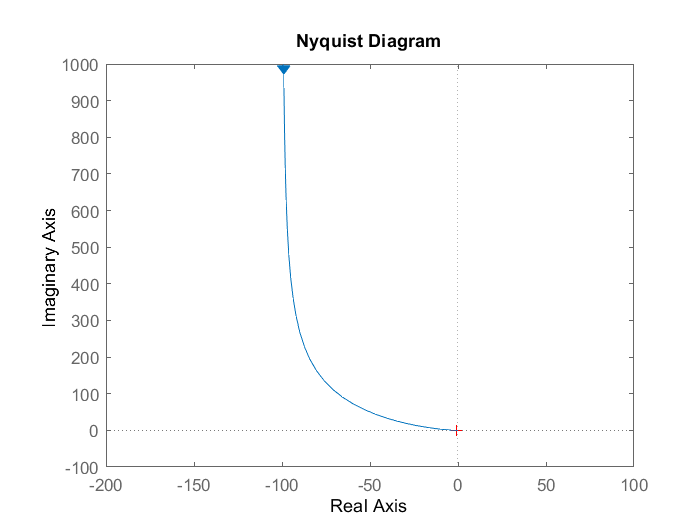


figure
P=nyquistplot(G0);
xlim([-200,100])
ylim([-100 1000])
setoptions(P,'ShowFullContour','off')

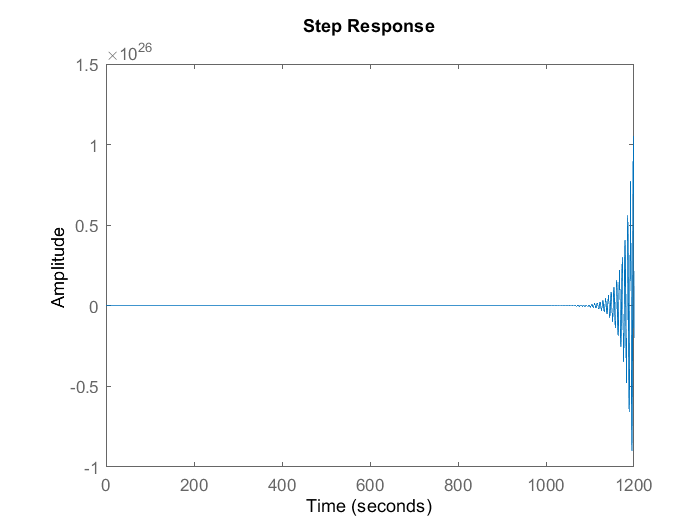


step(feedback(G0,1))

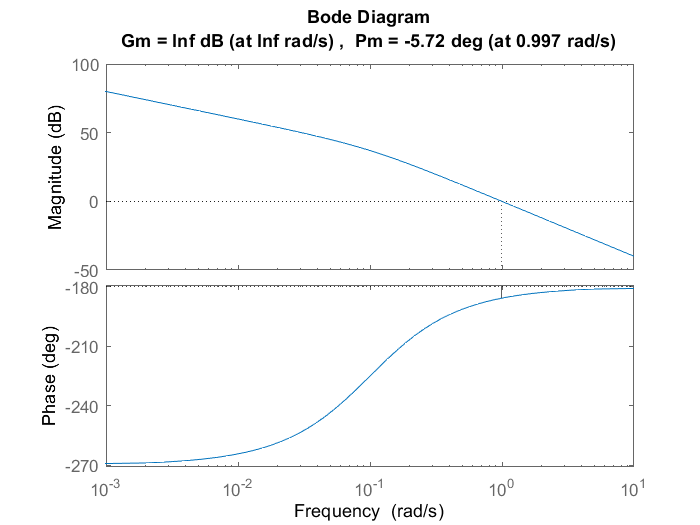

margin(G0)

20

G0=200*tf(conv([3 1],[2 1]),conv(conv([50 1 0],[10 1]),conv([0.5 2],[0.1 1])));G0=zpk(G0)

G0 =
 
       48 (s+0.5) (s+0.3333)
  -------------------------------
  s (s+10) (s+4) (s+0.1) (s+0.02)
 
Continuous-time zero/pole/gain model.



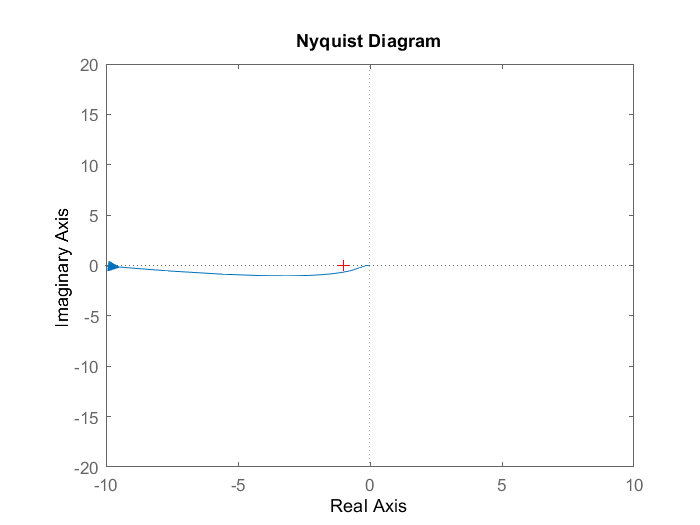

% figure
% bode(G0);
% grid on;

figure
P=nyquistplot(G0);
xlim([-10 10])
ylim([-20 20])
setoptions(P,'ShowFullContour','off')

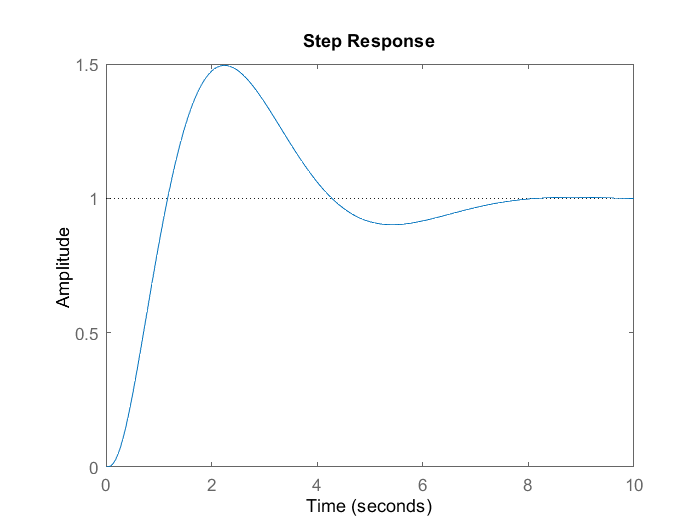


step(feedback(G0,1))

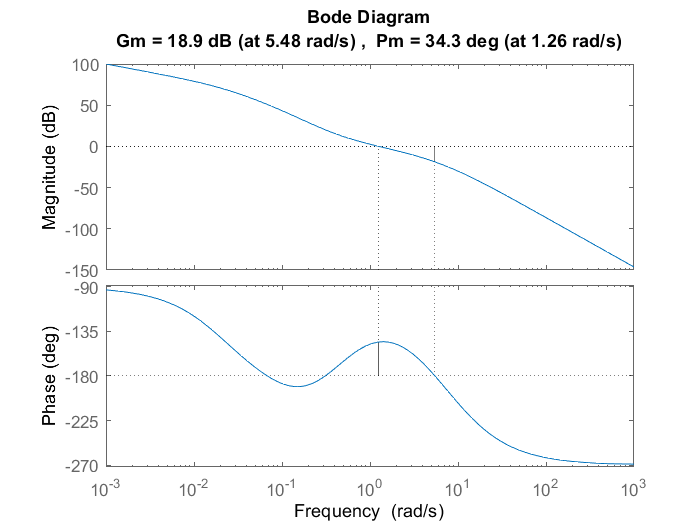

margin(G0)

G0=zpk([-0.1],[0 0 -1 -1/5],1/5)

G0 =
 
     0.2 (s+0.1)
  -----------------
  s^2 (s+1) (s+0.2)
 
Continuous-time zero/pole/gain model.



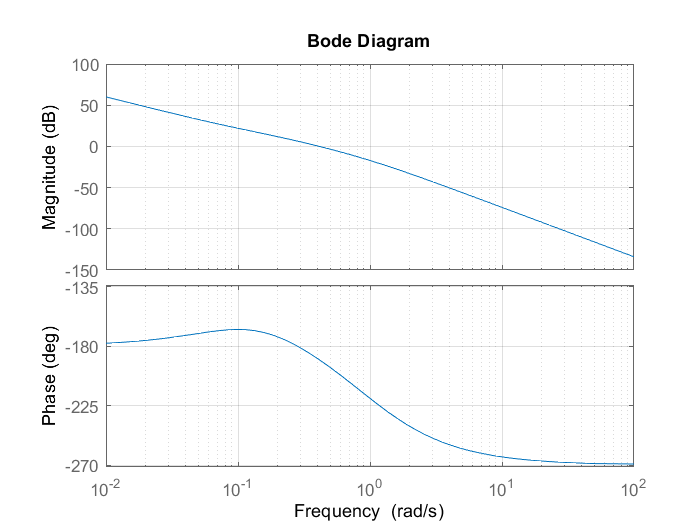

figure
bode(G0);
grid on;

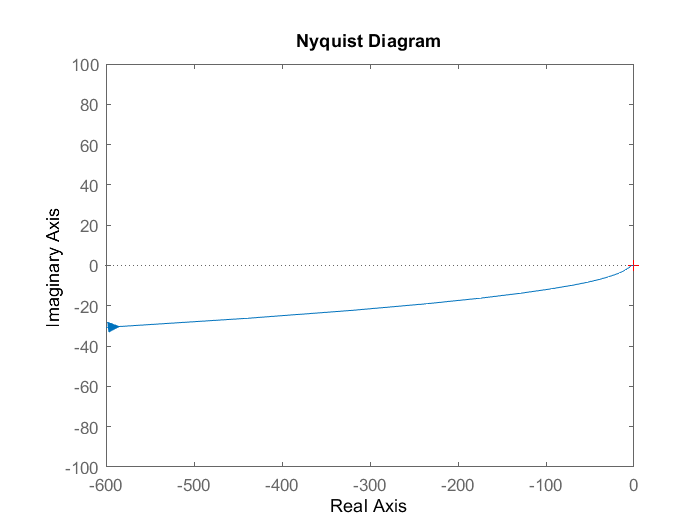


figure
P=nyquistplot(G0);
ylim([-100 100])
setoptions(P,'ShowFullContour','off')

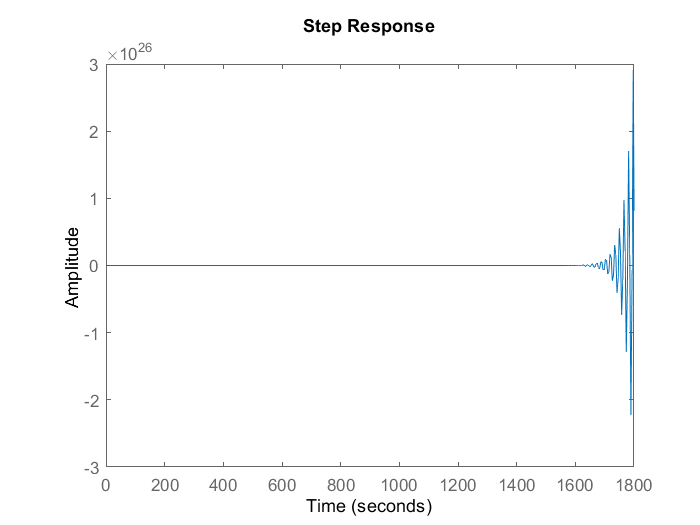


step(feedback(G0,1))

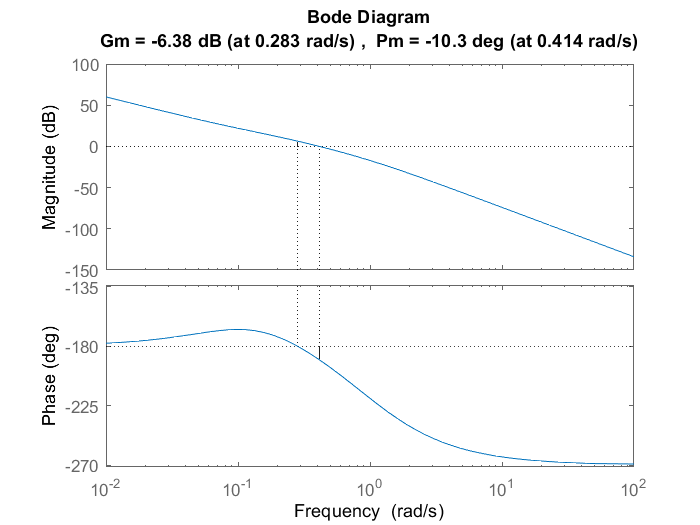

G0 =
 
  5 (s+0.2) (s+1)
  ---------------
        s^3
 
Continuous-time zero/pole/gain model.



margin(G0)